clear variables
% read in a default audio file
% clip to 660992
% [s, Fs] = audioread('guitartune.wav');
% s = s(1:660992);
% length(s)
[s, Fs] = audioread('try6clip.caf');

% counter = 1;
x = s(1:2:length(s))

x =     0.0003
    0.0020
    0.0027
    0.0011
   -0.0013
   -0.0021
   -0.0014
   -0.0010
    0.0007
    0.0070


r = s(2:2:length(s))

r =     0.0024
    0.0082
   -0.0101
    0.0038
    0.0014
   -0.0059
   -0.0020
    0.0015
    0.0160
    0.0124


% for i=1:2:length(s)
%     x(counter) = s(i);
%     r(counter) = s(i+1);
%     counter = counter + 1;
% end

% counter = 1;
% for i = 1:2:length(s)-1
%     x(counter) = s(i);
%     counter = counter + 1;
% end
% counter = 1;
% for i = 2:2:length(s)
%      r(counter) = s(i);
%      counter = counter + 1;
% end

epochs = 10;
var = 2e-5;

% filter order (idk what number we want)
L = 25; 

% get filter coeffs
[hb, ha] = cheby2(6, 30, 0.55)

hb =     0.1382    0.4319    0.7923    0.9526    0.7923    0.4319    0.1382


ha =     1.0000    0.5015    1.1616    0.5282    0.3628    0.1038    0.0196


mu = 0.001/((L+1)*var)

mu = 1.9231

% all eigenvalues are equal to var since R = var*I

rand_n = randn(size(s));
r = sqrt(var)*rand_n;
rf = filter(hb, ha, r)

rf =     0.0003
    0.0020
    0.0027
    0.0011
   -0.0013
   -0.0021
   -0.0014
   -0.0010
    0.0007
    0.0070


x = s + rf

x =     0.0003
    0.0020
    0.0027
    0.0011
   -0.0013
   -0.0021
   -0.0014
   -0.0010
    0.0007
    0.0070


avg_noise = zeros(size(s));

for q = 1 
    y = zeros(length(s),1);
    e = zeros(length(s),1);
    w = zeros(1, L+1);

    for k = L+1:length(s)
        r_clip = r(k:-1:k-L);
        y(k) = w*r_clip;
        e(k) = x(k) - y(k);
        w = w + 2*mu*e(k)*r_clip.';
    end
    
%     avg_noise = avg_noise + (s-e).^2;
end
% sound(x, Fs/2)

avg_noise = zeros(size(s));

for q = 1 
    y = zeros(length(s)/2,1);
    e = zeros(length(s)/2,1);
    w = zeros(1, L+1);

    for k = L+1:length(s)/2
        r_clip = r(k:-1:k-L);
        y(k) = w*r_clip;
        e(k) = x(k) - y(k);
        w = w + 2*mu*e(k)*r_clip.';
    end
    
%     avg_noise = avg_noise + (s-e).^2;
end

% E = zeros(661500, 1)
% for q = 1 
%     for i = 1:256:661244
%         y = zeros(256, 1);
%         e = zeros(256, 1);
%         w = zeros(1, L+1);
%         
%         for k = i+L+1:256+i
%             r_clip = r(k:-1:k-L);
%             y(k) = w*r_clip;
%             e(k) = x(k) - y(k);
%             w = w + 2*mu*e(k)*r_clip.';
%         end
% 
%         for j = 1:256
%             E(i + (j-1), 1) = e(j);
%         end
%     end
% %     avg_noise = avg_noise + (s-e).^2;
% end

% avg_noise = avg_noise / epochs

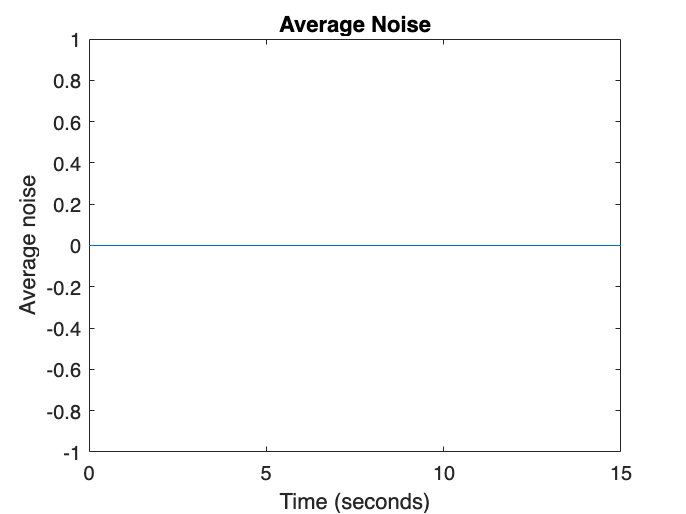

plot((0:length(s)-1)/Fs, avg_noise)
xlabel('Time (seconds)')
ylabel('Average noise')
title('Average Noise')

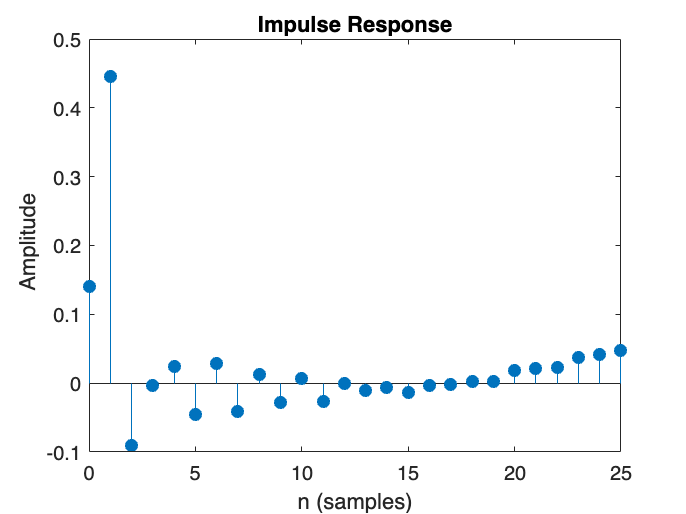

impz(w)

[H, w1] = freqz(hb,ha)

H =    1.0000 + 0.0000i
   1.0000 - 0.0076i
   0.9999 - 0.0151i
   0.9997 - 0.0227i
   0.9995 - 0.0303i
   0.9993 - 0.0378i
   0.9990 - 0.0454i
   0.9986 - 0.0530i
   0.9982 - 0.0605i
   0.9977 - 0.0681i


w1 =          0
    0.0061
    0.0123
    0.0184
    0.0245
    0.0307
    0.0368
    0.0430
    0.0491
    0.0552


H2 = freqz(w, 1, w1)

H2 =    0.5802 + 0.0000i
   0.5786 - 0.0219i
   0.5735 - 0.0432i
   0.5653 - 0.0636i
   0.5540 - 0.0824i
   0.5399 - 0.0993i
   0.5233 - 0.1138i
   0.5046 - 0.1257i
   0.4843 - 0.1346i
   0.4627 - 0.1402i


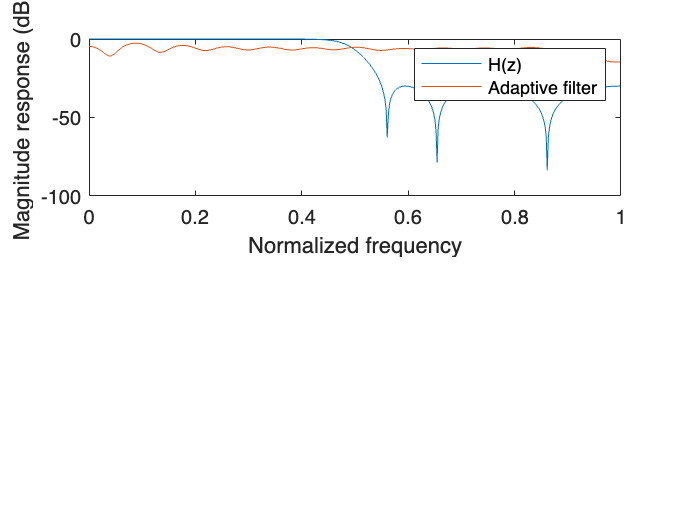

subplot(211)
plot(w1/pi, 20*log10(abs(H)))
hold on;
plot(w1/pi, 20*log10(abs(H2)))
xlabel('Normalized frequency')
ylabel('Magnitude response (dB)')
legend('H(z)', 'Adaptive filter')
hold off

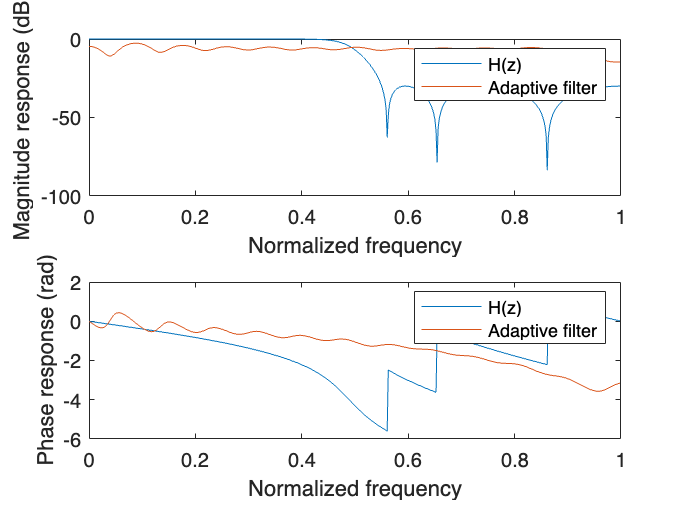

subplot(212)
plot(w1/pi, unwrap(angle(H)))
hold on;
plot(w1/pi, unwrap(angle(H2)))
xlabel('Normalized frequency')
ylabel('Phase response (rad)')
legend('H(z)', 'Adaptive filter')
hold off

 sound(e, Fs)